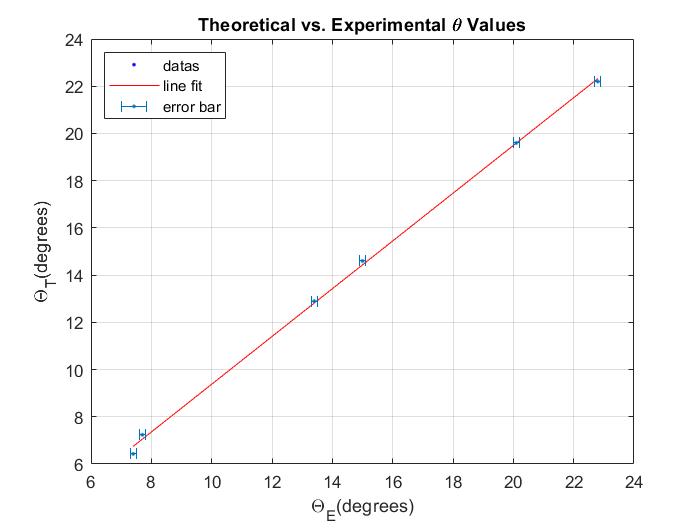


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( X, Y );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );

grid on



xlabel('\Theta_E(degrees)')
ylabel('\Theta_T(degrees)')

%error bar
hold on 

err=[0.1 0.1 0.1 0.1 0.1 0.1];
errorbar(X,Y,err, 'horizontal', '.')

legend({'datas','line fit','error bar'}, 'location','NorthWest');

title('Theoretical vs. Experimental \theta Values')





%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       1.011  (0.9688, 1.054)      \pm 0.021
 %      p2 =     -0.7345  (-1.394, -0.07466)   \pm 0.3298

%Goodness of fit:
 % SSE: 0.1863
  %R-square: 0.9991
 % Adjusted R-square: 0.9989
  %RMSE: 0.2158